1-0.2-0.2-0.2-0.2-0.2

ans = 5.5511e-17

0.2 bestaat niet in matlab, wel een benadering

cos(pi/2)

ans = 6.1232e-17

Pi bestaat niet, cos is ook een benadering

48-41

ans = 7

4.8-4.1 % - 0.7 -> 2.2204e-16

ans = 2.2204e-16

51-44 % - 7

ans = 0

5.1-4.4 % - 0.7 -> -6.6613e-16

ans = -6.6613e-16

Afrondingsfouten bij floats

a = 1e-16 + 1 - 1e-16;
b = 1e-16 - 1e-16 +1;
abs (a-b)

ans = 1.1102e-16

Bij een klein getal is meer precisie

1-3*(4/3 - 1) % afrondingsfouten

ans = 2.2204e-16

1-3*(sym(4/3) - 1) % symbolisch

$$ans = 0$$

**2.6 **gelijkheid tussen x + 1 en xeps

clear ; close all; clc

x = logspace(-10,10);
y = eps(x) ./ x;
semilogx(x,y)
% ==[pretifications]==
grid on
hold on
semilogx([x(1), x(length(x))], [1.6e-16, 1.6e-16]) %idk why 1.6 actually :/
title("Evolutie van eps(x)=x in functie van x")
ylabel("eps(x)/x"); xlabel("x")
legend("RE", "Mean Error")
% ====

**2.7 **x+1 == x

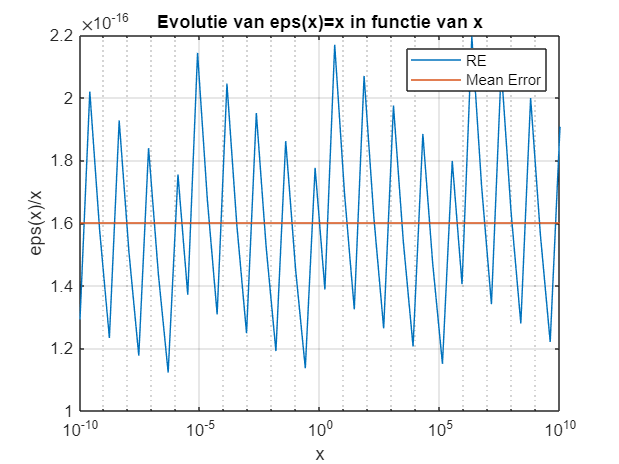

hold off


x = logspace(0,40);
y = eps(x);
loglog(x,y)
%% ==
grid on
hold on
loglog([x(1), x(length(x))], [1, 1]) % 1 Because we want x + 1 to round to x
title("Evolutie van eps(x)=x in functie van x")
ylabel("eps(x)"); xlabel("x")
legend("AE", "Rounding treshold")
% ==
title("Evolutie van eps(x)=x in functie van x")
ylabel("eps(x)/x"); xlabel("x")
legend("RE", "Mean Error")

**2.8 **Lim e

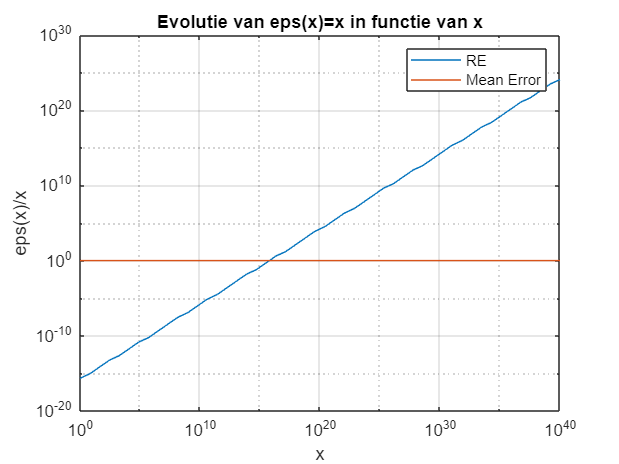

hold off


f = @(t) (1+1./t).^t; % Change function here
syms t
sol = limit(f(t),t, inf); % Correct value calculated symbolically (could fail)
x = logspace(0,20,21);
y = abs(f(x) - sol)/sol

$$y = \left(\begin{array}{ccccccccccccccccccccc} {\mathrm{e}}^{-1}\,\left(\mathrm{e}-2\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{2920294394200351}{1125899906842624}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{761337409643085}{281474976710656}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{6117968804405101}{2251799813685248}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{6120720491593683}{2251799813685248}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{6120995910056143}{2251799813685248}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{3060511726927033}{1125899906842624}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{3060513106195321}{1125899906842624}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{6121026447062581}{2251799813685248}\right) & -{\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{6121027018263585}{2251799813685248}\right) & -{\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{95641047203407}{35184372088832}\right) & -{\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{3060513510646747}{1125899906842624}\right) & -{\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{6121570701875621}{2251799813685248}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{1529034017176379}{562949953421312}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{3058068034352895}{1125899906842624}\right) & -{\mathrm{e}}^{-1}\,\left(\mathrm{e}-\frac{1708572928158949}{562949953421312}\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right) & {\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right) \end{array}\right)$$

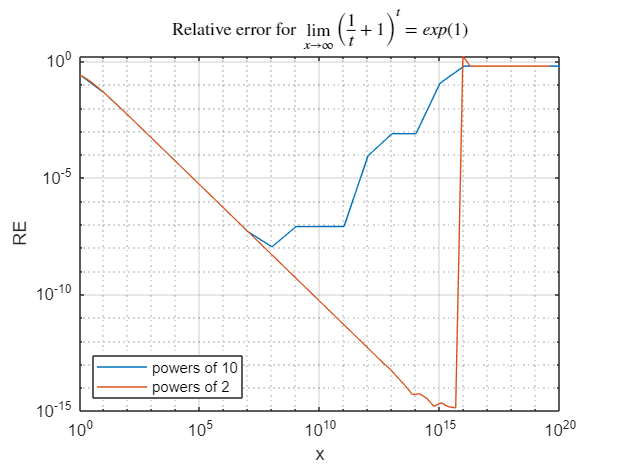

loglog(x , y)

hold on
grid on
x2 = logspace(0,log10(2^65), 66);
y2 = abs(f(x2) - sol)/sol;
loglog(x2,y2)
legend({'powers of 10','powers of 2'}, "Location", "southwest")
ylabel("RE")
xlabel("x")
title("Relative error for $\lim_{x \to \infty} "+latex(sym(f))+"="+string(sol)+"$", "Interpreter","latex");
hold off

**2.9**

realmin

ans = 2.2251e-308

2^(-1022)

ans = 2.2251e-308

realmax

ans = 1.7977e+308

(2-2^(-52))*2^(1023)

ans = 1.7977e+308


$$x=(-1)^{s} \cdot (1+m) \cdot 2^e$$
